# **Mecánica de fluidos: ejercicios.**

## Ejercicio 1:

Sabiendo que el agua alcanza una profundidadd *h = 750 m *en la pared vertical de la represa mostrada en la siguiente figura y que la pared tiene un ancho *D =  300 m, *hallar:

- La fuerza horizontal resultante ejercida por la presión nanométrica del agua sobre la pared de la represa.

- Hallar el momento de fuerza$\left.\left(\tau \right)\right)$ que hace tender a girar la represa alrededor del eje *pp'.*

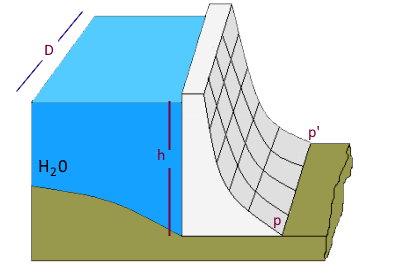

### solución:

Las ecuaciones a utilizar para la solución de el ejercicio estan dadas por las siguientesexpresiones:


$$F=P*A$$


Dónde F es la fuerza ejercida y P es la Presión


$$P=P_0 +\rho *g*h$$


Donde $P_0$ es la Presión atmosférica sobre el agua, $\rho$ es la densidad del agua, $g\;$es la aceleración de la gravedad y $h$ es la altura. Dado que el ejercicio habl de la presión nanométrica del agua sobre la pared, exige que no sea tenida en cuenta la presión atmosférica entonces la anterior expresión se reduce a :


$$P=\rho *g*h$$


Ahora, como la presión no es uniforme en toda la superficie de la pared de la represa, sino que depende de la profundidad $h$ se debe tomar un diferencial de altura $\delta h$ y encontar el diferencias de fuerza $\delta F$. como se muestra en la siguiente figura:

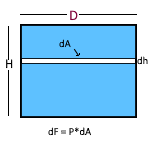

Sabemos que: 


$$\delta F= p*\delta A$$


Reemplazando nos queda:


$$ \delta F = (\rho \cdot g \cdot h ) \cdot (D \cdot \delta h)$$


La Fuerza total resultante será la sumatoria de todas las  $\delta F$ entre 0 y *H, *es decir, la integral definida del diferencial de fuerza:


$$\int \delta F =  \int \! (\rho \cdot g \cdot h ) \cdot (D \cdot \delta h)$$


Resolviendo para toda la pared:


$$\int_{0}^{H}   \rho \cdot g\cdot D \, \cdot  h \, \cdot \delta h = \rho \cdot g \cdot D \, \cdot \int_{0}^{H}  h \, \cdot \delta h$$


Resolviendo la integral:


$$\Rightarrow F =  \rho \cdot g \cdot  D \cdot \,\int_{0}^{H}  h \, \cdot \delta h = 1/2\cdot  \rho \cdot g \cdot D \cdot H^{2}$$


El valor de la densidad del agua  $\rho$ es 1000, al evaluar el resultado reemplazando los valores del ejercicio: 


$$F = 1/2 \cdot 1000 \cdot 9.8 \cdot 750 \cdot 90000  = 3.3075 \times 10^{11} \, Newton.$$


Ahora, el torque o momento de la fuerza $\delta T$ respecto del eje *pp'* está definido por la expresión:


$$     \delta \tau = (H-h)\cdot \delta F = \rho \cdot g \cdot D\cdot h \cdot (H-h)\cdot \delta h$$


y el torque resultante es:


$$\tau = \int_{0}^{H}\delta \tau  = \rho \cdot g \cdot D \cdot \int_{0}^{H} h\cdot (H-h)\cdot \delta h$$


Resolviendo:


$$\tau = 1/6 \cdot \rho \cdot g \cdot D\cdot H^{3}$$


Sustituyendo los valores tenemos:


$$   \tau = 1/6 \cdot 1000 \cdot 9.8 \cdot 750\cdot 300^{3} =  3.3075 \times 10^{13} Newton$$


### Verificación:

Primero esto creamos las  variables  que  influyen el el sistema:

Definicion de variables:

D = 750
H = 300
rho = 1000
g = 9.8

Calculo del Fuerza y torque:

F = (1/2)* rho*g*D*H^2
tau = (1/6)*rho*g*D*H^3

### Simulación interactiva:

En este ejercicio se puede observar el comportamineto de las fuerza y del torque con diferentes valores de altura, longitud y densidad del liquido

Altura = 310        
Longitud = 250
deltaRho = 1.14
H = Altura;
D = Longitud;
Newrho = rho * deltaRho
F = (1/2)* Newrho*g*D*H^2
tau = (1/6)*Newrho*g*D*H^3